# example


s=tf('s');

Transfer function:

G=(s+2)/(s^2+2*s+3);


The product of two transfer functions is obtained by:

G12 = G1 * G2;

For a system with 2 inputs and 2 outputs, the closed-loop transfer matrix is obtained

with

S=feedback(eye(2),G*F);
T=feedback(G*F,eye(2));

For a SISO system this can be written:

S=1/(1+G*F);
T=G*F/(1+G*F);

For numerical reasons it is very important to use the function minreal, for example

minreal(T). This creates an equivalent system where all canceling pole/zero pair,

corresponding to unobservable or uncontrollable states, are eliminated.

The bode diagram for G is plotted by typing:

bode(G);

OR:

bode(G,{wmin,wmax});

Amplitude and phase at a given frequency are obtained by:

[m,p]=bode(G,w);

Phase margin, amplitude margin and corresponding frequencies are obtained by:

[Gm,Pm,wp,wc]=margin(G*F);

To simulate a step response in the control signal, use the function:

step(G);

OR:

step(G,tfinal);

In the same way, to simulate a step response in the reference signal, we type:

step(T);


# 4.1

## 4.1.1

s=tf('s');
G = (3*(-s+1))/((5*s+1)*(10*s+1));

w_cd = 0.4;
[m,p] = bode(G,w_cd)

m = 0.3505

p = 198.7999

p_margin = -180 + p; 
p_d = 30;
p_lag = 6;
p_max = p_d-p_margin + p_lag

p_max = 17.2001


beta = 0.5455;
t_d = 1/(w_cd*sqrt(beta))

t_d = 3.3849


%G_abs = sqrt(3^2+(3*0.4)^2)/sqrt((1-50*0.4^2)^2+(15*0.4)^2)
K = sqrt(beta)/m

K = 2.1074

t_i = 10/w_cd

t_i = 25

gamma = 0;

F_lead = ((t_d*s+1)/(beta*t_d*s+1));
F_lag = ((t_i*s+1)/(t_i*s+gamma));
F=K*F_lead*F_lag


F =
 
  178.3 s^2 + 59.82 s + 2.107
  ---------------------------
       46.16 s^2 + 25 s
 
Continuous-time transfer function.




T=G*F/(1+G*F);

%step(T,70)
%bode(F*G)

[Gm,Pm,wp,wc]=margin(G*F)

Gm = 2.1512

Pm = 30.0012

wp = 0.7086

wc = 0.4015

## 4.1.2

G_c = F*G/(1+F*G)


G_c =
 
                                                                            
  -1.235e06 s^7 - 2.186e05 s^6 + 8.649e05 s^5 + 4.873e05 s^4 + 9.409e04 s^3 
                                                                            
                                                     + 6991 s^2 + 158.1 s   
                                                                            
  --------------------------------------------------------------------------
                                                                           
  5.327e06 s^8 + 7.732e06 s^7 + 5.499e06 s^6 + 2.616e06 s^5 + 7.618e05 s^4 
                                                                           
                                      + 1.151e05 s^3 + 7616 s^2 + 158.1 s  
                                                                           
 
Continuous-time transfer function.



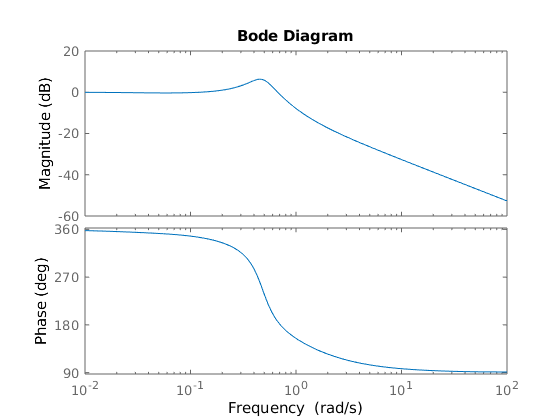

bode(G_c)

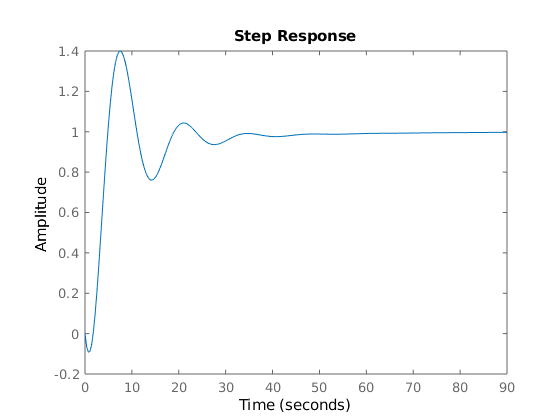

step(G_c)

Bandwidth:

w_b = 0.77 rad/s

Resonance peak:

M_T = 6.36 dB at w_r = 0.45 rad/s

Overshot:

40%

Rise time:

2.39 s

## 4.1.3

beta = 0.246;
t_d = 1/(w_cd*sqrt(beta))

t_d = 5.0405

K = sqrt(beta)/m

K = 1.4152


F_lead = ((t_d*s+1)/(beta*t_d*s+1));
F_lag = ((t_i*s+1)/(t_i*s+gamma));
F=K*F_lead*F_lag


F =
 
  178.3 s^2 + 42.51 s + 1.415
  ---------------------------
         31 s^2 + 25 s
 
Continuous-time transfer function.




[Gm,Pm,wp,wc]=margin(G*F)

Gm = 2.5211

Pm = 50.0787

wp = 0.9577

wc = 0.4020


G_c = F*G/(1+F*G)


G_c =
 
                                             
  -8.292e05 s^7 - 2.86e05 s^6 + 6.727e05 s^5 
                                             
          + 3.701e05 s^4 + 6.753e04 s^3      
                                             
                       + 4806 s^2 + 106.1 s  
                                             
  -------------------------------------------
                                             
  2.402e06 s^8 + 4.487e06 s^7 + 3.914e06 s^6 
                                             
          + 2.143e06 s^5 + 6.207e05 s^4      
                                             
          + 8.783e04 s^3 + 5431 s^2          
                                             
                                  + 106.1 s  
                                             
 
Continuous-time transfer function.



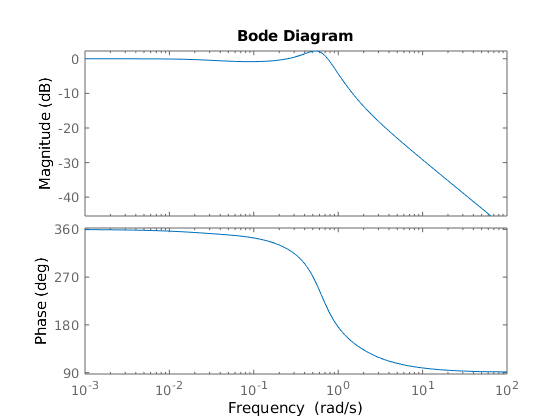

bode(G_c)

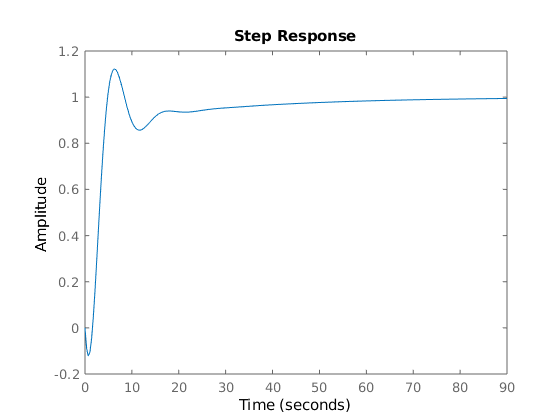

step(G_c)

Bandwidth:

w_b = 0.92 rad/s

Resonance peak:

M_T = 2.24 dB at w_r = 0.54 rad/s

Overshot:

12%

Rise time:

2.4 s

# 4.2

## 4.2.1

s=tf('s');
G=20/((s+1)*((s/20)^2+s/20 +1))


G =
 
               160000
  --------------------------------
  20 s^3 + 420 s^2 + 8400 s + 8000
 
Continuous-time transfer function.

